## Global Variables

% UR5e connection.
vm_host = '127.0.0.1';
real_host = '192.168.0.100';
port = 30003;

% DH parameters.
a = [0, -0.425, -0.3922, 0, 0, 0];
d = [0.1625, 0, 0, 0.1333, 0.0997, 0.0996];
alpha = [pi/2, 0, 0, pi/2, -pi/2, 0];

% Joint variable sets.
A = deg2rad([-90, -173, 132, 220, 0, 0]);
B = deg2rad([-90, -60, 90, 0, 90, 0]);

## Part A.2

The frame transformations of $A_{i}$ for $i \in [1, 6]$ relative to the previous frame are:


$${}^{i - 1}T_{i} = \pmatrix{
    \cos(A_{i}) & -\sin(A_{i}) \cos(\alpha_{i}) & \sin(A_{i}) \sin(\alpha_{i}) & a_{i} \cos(A_{i}) \cr
    \sin(A_{i}) & \cos(A_{i}) \cos(\alpha_{i}) & -\cos(A_{i}) \sin(\alpha_{i}) & a_{i} \sin(A_{i}) \cr
    0 & \sin(\alpha_{i}) & \cos(\alpha_{i}) & d_{i} \cr
    0 & 0 & 0 & 1 \cr
}$$


The frame transformations of $A_i$ relative to the base frame are:


$$\begin{array}{rcl}
{}^{0}T_{1} = {}^{0}T_{1} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    -1 & 0 & 0 & 0 \cr
    0 & 1 & 0 & 0.1625 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{2} = {}^{0}T_{1} \times {}^{1}T_{2} = {}^{0}T_{1} \times {}^{1}T_{2} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    0.9925 & -0.1219 & 0 & -0.4218 \cr
    -0.1219 & -0.9925 & 0 & 0.2143 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{3} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} = {}^{0}T_{2} \times {}^{2}T_{3} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    -0.7547 & -0.6561 & 0 & -0.1258 \cr
    -0.6561 & 0.7547 & 0 & 0.4716 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{4} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} = {}^{0}T_{3} \times {}^{3}T_{4} &= \pmatrix{
    0 & -1 & 0 & -0.1333 \cr
    0.9998 & 0 & -0.0175 & -0.1258 \cr
    0.0175 & 0 & 0.9998 & 0.4716 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{5} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} = {}^{0}T_{4} \times {}^{4}T_{5} &= \pmatrix{
    0 & 0 & -1 & -0.1333 \cr
    0.9998 & 0.0175 & 0 & -0.1276 \cr
    0.0175 & -0.9998 & 0 & 0.5713 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

\end{array}$$


Similarly for $B$:


$$\begin{array}{rcl}
{}^{0}T_{1} = {}^{0}T_{1} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    -1 & 0 & 0 & 0 \cr
    0 & 1 & 0 & 0.1625 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{2} = {}^{0}T_{1} \times {}^{1}T_{2} = {}^{0}T_{1} \times {}^{1}T_{2} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    -0.5 & -0.8660 & 0 & 0.2125 \cr
    -0.8660 & 0.5 & 0 & 0.5306 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{3} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} = {}^{0}T_{2} \times {}^{2}T_{3} &= \pmatrix{
    0 & 0 & -1 & 0 \cr
    -0.8660 & 0.5 & 0 & 0.5522 \cr
    0.5 & 0.8660 & 0 & 0.3345 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{4} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} = {}^{0}T_{3} \times {}^{3}T_{4} &= \pmatrix{
    0 & -1 & 0 & -0.1333 \cr
    -0.8660 & 0 & -0.5 & 0.5522 \cr
    0.5 & 0 & -0.8660 & 0.3345 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

{}^{0}T_{5} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} = {}^{0}T_{4} \times {}^{4}T_{5} &= \pmatrix{
    -1 & 0 & 0 & -0.1333 \cr
    0 & 0.5 & 0.8660 & 0.5023 \cr
    0 & 0.8660 & -0.5 & 0.2481 \cr
    0 & 0 & 0 & 1 \cr
} \\\\

\end{array}$$


% Compute each frame transformation according to A and B.
T_A = compute_frame_transforms(A, a, d, alpha)

T_A = T_A(:,:,1) =

    0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    0.1625
         0         0         0    1.0000


T_A(:,:,2) =

   -0.0000   -0.0000   -1.0000    0.0000
    0.9925   -0.1219   -0.0000   -0.4218
   -0.1219   -0.9925    0.0000    0.2143
         0         0         0    1.0000


T_A(:,:,3) =

    0.0000    0.0000   -1.0000    0.0000
   -0.7547   -0.6561   -0.0000   -0.1258
   -0.6561    0.7547    0.0000    0.4716
         0         0         0    1.0000


T_A(:,:,4) =

   -0.0000   -1.0000    0.0000   -0.1333
    0.9998   -0.0000   -0.0175   -0.1258
    0.0175    0.0000    0.9998    0.4716
         0         0         0    1.0000


T_A(:,:,5) =

   -0.0000   -0.0000   -1.0000   -0.1333
    0.9998    0.0175   -0.0000   -0.1276
    0.0175   -0.9998    0.0000    0.5713
         0         0         0    1.0000


T_A(:,:,6) =

   -0.0000   -0.0000   -1.0000   -0.2329
    0.9998    0.0175   -0.0000   -0.127

T_B = compute_frame_transforms(B, a, d, alpha)

T_B = T_B(:,:,1) =

    0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    0.1625
         0         0         0    1.0000


T_B(:,:,2) =

   -0.0000    0.0000   -1.0000    0.0000
   -0.5000   -0.8660   -0.0000    0.2125
   -0.8660    0.5000    0.0000    0.5306
         0         0         0    1.0000


T_B(:,:,3) =

    0.0000    0.0000   -1.0000   -0.0000
   -0.8660    0.5000   -0.0000    0.5522
    0.5000    0.8660    0.0000    0.3345
         0         0         0    1.0000


T_B(:,:,4) =

    0.0000   -1.0000   -0.0000   -0.1333
   -0.8660   -0.0000   -0.5000    0.5522
    0.5000    0.0000   -0.8660    0.3345
         0         0         0    1.0000


T_B(:,:,5) =

   -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.5023
    0.0000    0.8660   -0.5000    0.2481
         0         0         0    1.0000


T_B(:,:,6) =

   -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.588

## Part A.3

The forward kinematic solution, ${}^{0}T_{6}$, for joint variable set $A$ is:


$${}^{0}T_{6} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} \times {}^{5}T_{6} = {}^{0}T_{5} \times {}^{5}T_{6} = \pmatrix{
    0 & 0 & -1 & -0.2329 \cr
    0.9998 & 0.0175 & 0 & -0.1276 \cr
    0.0175 & -0.9998 & 0 & 0.5713 \cr
    0 & 0 & 0 & 1 \cr
}$$


The forward kinematic solution, ${}^{0}T_{6}$, for joint variable set $B$ is:


$${}^{0}T_{6} = {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} \times {}^{5}T_{6} = {}^{0}T_{5} \times {}^{5}T_{6} = \pmatrix{
    -1 & 0 & 0 & -0.1333 \cr
    0 & 0.5 & 0.8660 & 0.5886 \cr
    0 & 0.8660 & -0.5 & 0.1983 \cr
    0 & 0 & 0 & 1 \cr
}$$


T_A(:, :, 6)

ans =    -0.0000   -0.0000   -1.0000   -0.2329
    0.9998    0.0175   -0.0000   -0.1276
    0.0175   -0.9998    0.0000    0.5713
         0         0         0    1.0000


T_B(:, :, 6)

ans =    -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.5886
    0.0000    0.8660   -0.5000    0.1983
         0         0         0    1.0000


## Part A.4

The forward kinematic solutions were verified with `fkine.`

% Create links from DH parameters.
L(1) = Link('revolute', 'd', d(1), 'a', a(1), 'alpha', alpha(1));
L(2) = Link('revolute', 'd', d(2), 'a', a(2), 'alpha', alpha(2));
L(3) = Link('revolute', 'd', d(3), 'a', a(3), 'alpha', alpha(3));
L(4) = Link('revolute', 'd', d(4), 'a', a(4), 'alpha', alpha(4));
L(5) = Link('revolute', 'd', d(5), 'a', a(5), 'alpha', alpha(5));
L(6) = Link('revolute', 'd', d(6), 'a', a(6), 'alpha', alpha(6));
robot = SerialLink(L);

% Perform forward kinematics from joint variable sets A and B.
T_A_verified = robot.fkine(A)

 

T_A_verified = 
         0         0        -1   -0.2329
    0.9998    0.0175         0   -0.1276
    0.0175   -0.9998         0    0.5713
         0         0         0         1


T_B_verified = robot.fkine(B)

 

T_B_verified = 
        -1         0         0   -0.1333
         0    0.5000    0.8660    0.5886
         0    0.8660   -0.5000    0.1983
         0         0         0         1


## Part A.5

The forward kinematic solutions were verified in the URsim.

## Part B.1.a

The Jacobian matrix is a generalisation of all of the first-order partial derivatives of a function, $f: \mathbb{R}^{N} \rightarrow \mathbb{R}^{M}$, with respect to a given point, $x$:


$$J = \pmatrix{\frac{\partial\vec{f}}{\partial x_1} & \dots & \frac{\partial\vec{f}}{\partial x_n}} = \pmatrix{\frac{\partial f_{1}}{\partial x_{1}} & ... & \frac{\partial f_{1}}{\partial x_{n}} \cr
        \vdots & \ddots & \vdots \cr
        \frac{\partial f_{m}}{\partial x_{1}} & ... & \frac{\partial f_{m}}{\partial x_{n}}}$$


The inverse Jacobian matrix is the Jacobian of an invertible function, $f: \mathbb{R}^{N} \leftarrow \mathbb{R}^{M}$:


$$J^{-1}_{f} = J_{f^{-1}}$$


In the context of robotic arms, the Jacobian matrix is used to transform a vector of joint angular velocities to a vector of end effector velocities at a set of joint angular positions (i.e. perform forward kinematics). The inverse Jacobian matrix is used to transform a vector of end effector velocities to a vector of joint angular velocities at a set of joint angular positions (i.e. perform inverse kinematics).

## Part B.1.b

Let:

- 
$${}^{0}z_{i} = {}^{0}T_{i}(\text{row}=1,2,3)(\text{col}=3)$$


- 
$${}^{0}o_{i} = {}^{0}T_{i}(\text{row}=1,2,3)(\text{col}=3)$$


So (for a revolute joint $i$):


$$J_{i} = \pmatrix{
{}^{0}z_{i - 1} \times \left({}^{0}o_{n} - {}^{0}o_{i - 1} \right) \cr
{}^{0}z_{i - 1}
}$$



$$J = \pmatrix{J_{v} \cr J_{w}} = \pmatrix{J_{1} & \dots & J_{n}}$$


[J_A, z_A, o_A] = compute_jacobian(T_A)
[J_B, z_B, o_B] = compute_jacobian(T_B)

## Part B.1.c

The Jacobian is verified using `jacob0.`

J_A_verified = robot.jacob0(A)

J_A =     0.1276   -0.0000   -0.0000   -0.0000   -0.0000         0
   -0.2329    0.4088    0.3570    0.0997   -0.0996   -0.0000
         0    0.1276   -0.2943    0.0017   -0.0017   -0.0000
         0   -1.0000   -1.0000   -1.0000    0.0000   -1.0000
         0   -0.0000   -0.0000   -0.0000   -0.0175   -0.0000
    1.0000    0.0000    0.0000    0.0000    0.9998    0.0000


z_A = z_A(:,:,1) =

     0
     0
     1


z_A(:,:,2) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,3) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,4) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,5) =

    0.0000
   -0.0175
    0.9998


z_A(:,:,6) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,7) =

   -1.0000
   -0.0000
    0.0000


o_A = o_A(:,:,1) =

     0
     0
     0


o_A(:,:,2) =

         0
         0
    0.1625


o_A(:,:,3) =

    0.0000
   -0.4218
    0.2143


o_A(:,:,4) =

    0.0000
   -0.1258
    0.4716


o_A(:,:,5) =

   -0.1333
   -0.1258
    0.4716


o_A(:,:,6) =

   -0.1333
   -0.1276
    0.5713


o_A(:,:,7) =

   -0.2329
   -0.1276
    0.5713


J_B_verified = robot.jacob0(B)

J_B =    -0.5886   -0.0000   -0.0000    0.0000    0.0996    0.0000
   -0.1333    0.0358   -0.3322   -0.1361    0.0000    0.0000
         0   -0.5886   -0.3761   -0.0364   -0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.5000    0.8660
    1.0000    0.0000    0.0000    0.0000   -0.8660   -0.5000


z_B = z_B(:,:,1) =

     0
     0
     1


z_B(:,:,2) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,3) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,4) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,5) =

   -0.0000
   -0.5000
   -0.8660


z_B(:,:,6) =

   -0.0000
    0.8660
   -0.5000


z_B(:,:,7) =

   -0.0000
    0.8660
   -0.5000


o_B = o_B(:,:,1) =

     0
     0
     0


o_B(:,:,2) =

         0
         0
    0.1625


o_B(:,:,3) =

    0.0000
    0.2125
    0.5306


o_B(:,:,4) =

   -0.0000
    0.5522
    0.3345


o_B(:,:,5) =

   -0.1333
    0.5522
    0.3345


o_B(:,:,6) =

   -0.1333
    0.5023
    0.2481


o_B(:,:,7) =

   -0.1333
    0.5886
    0.1983


## Part B.1.d

Consider the end effector velocity with a velocity of ${}^{0}\dot{d}_{6}$ and passing through $A$ where:


$${}^{0}\dot{d}_{6} = \pmatrix{0.25 \cr 0 \cr 0 \cr 0 \cr 0 \cr 0}$$


The instantaneous velocity of the end effector is:

d_dot_A_6 = [0.25; 0; 0; 0; 0; 0];

J_A_verified =     0.1276   -0.0000   -0.0000   -0.0000    0.0000         0
   -0.2329    0.4088    0.3570    0.0997   -0.0996         0
    0.0000    0.1276   -0.2943    0.0017   -0.0017         0
         0   -1.0000   -1.0000   -1.0000    0.0000   -1.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0175   -0.0000
    1.0000    0.0000    0.0000    0.0000    0.9998    0.0000


v_A = pinv(J_A) * d_dot_A_6

J_B_verified =    -0.5886   -0.0000   -0.0000    0.0000    0.0996         0
   -0.1333    0.0358   -0.3322   -0.1361    0.0000         0
   -0.0000   -0.5886   -0.3761   -0.0364   -0.0000         0
         0   -1.0000   -1.0000   -1.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.5000    0.8660
    1.0000    0.0000    0.0000    0.0000   -0.8660   -0.5000


## Part B.1.e

## Part B.2

Consider the joint angular velocities at $B$:


$$\dot{\theta} = \pmatrix{1 \cr 0.1 \cr 0.1 \cr 0.1 \cr 0.1 \cr 0.1}$$


The end effector velocity is therefore:

theta_dot_B = [1; 0.1; 0.1; 0.1; 0.1; 0.1];
d_dot_B_6 = J_B * theta_dot_B

v_A =     1.9236
    0.4923
    0.2234
   -0.2458
   -1.9233
   -0.4698


## Part C.1

Drawing the trajectory of poses 1-5 using `movel`.

% Define poses.
pose1 = [-588.53, -133.30, 100, 2.2214, -2.2214, 0];
pose2 = [-688.53, -133.30, 100, 2.2214, -2.2214, 0];

d_dot_B_6 =    -0.5786
   -0.1766
   -0.1001
   -0.3000
    0.0366
    0.8634


pose3 = [-688.53, -233.30, 100, 2.2214, -2.2214, 0];
pose4 = [-588.53, -233.30, 100, 2.2214, -2.2214, 0];

% Create moves from poses.
move1 = UR5eMove('l', pose1);
move2 = UR5eMove('l', pose2);
move3 = UR5eMove('l', pose3);
move4 = UR5eMove('l', pose4);

% Execute moves.
ur5e = UR5e(vm_host, port);
ur5e.add_move(move1, move2, move3, move4);
ur5e.execute();
ur5e.draw(1, 0, 0, 0, 0);

## Functions

Helper function to compute frame transforms from DH parameters.

function T = compute_frame_transforms(theta, a, d, alpha)

UR5e connection Established!
Socket Disconnected!


    % Frame transformations of i relative to i-1.
    T_ij = zeros(4, 4, length(theta));

Program started.
Moving to [-6.885300e+02, -1.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-6.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-5.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Succeeded!
Program completed.


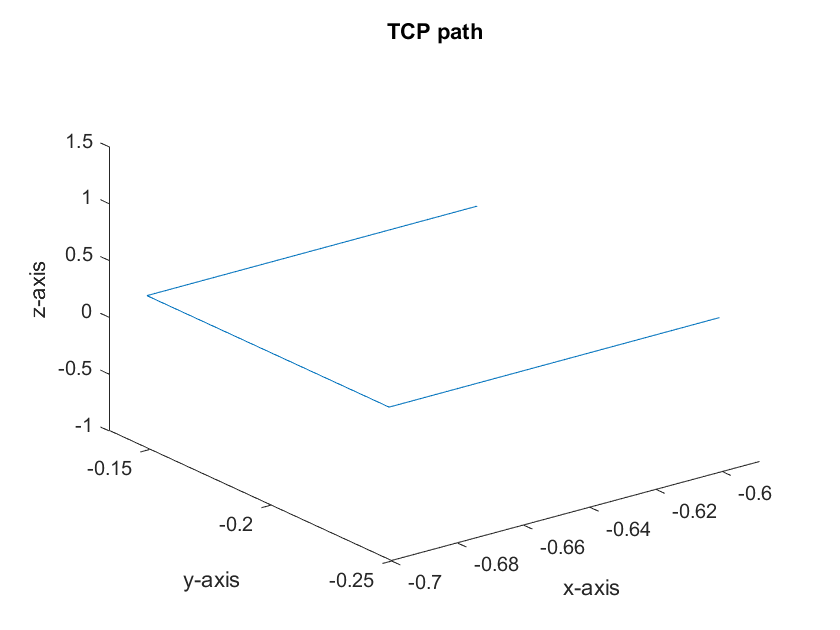

    for i = 1:length(theta)

        T_ij(:, :, i) = [
            cos(theta(i)), -sin(theta(i)) * cos(alpha(i)), sin(theta(i)) * sin(alpha(i)), a(i) * cos(theta(i));
            sin(theta(i)), cos(theta(i)) * cos(alpha(i)), -cos(theta(i)) * sin(alpha(i)), a(i) * sin(theta(i));
            0, sin(alpha(i)), cos(alpha(i)), d(i);
            0, 0, 0, 1
        ];
    end

    % Frame transformations of i relative to 0.
    T = zeros(4, 4, length(theta));
    T(:, :, 1) = T_ij(:, :, 1);
    for i = 2:length(theta)
        T(:, :, i) = T(:, :, i - 1) * T_ij(:, :, i);
    end
end

Helper function to compute Jacobian matrices from frame transforms.

function [J, z, o] = compute_jacobian(T)
    n = length(T);

    % Get the rotation and translation vectors from each frame transform.
    z = zeros(3, 1, n + 1);
    o = zeros(3, 1, n + 1);
    z(:, :, 1) = [0; 0; 1];
    o(:, :, 1) = [0; 0; 0];
    for i = 1:n
        z(:, :, i + 1) = T(1:3, 3, i)';
        o(:, :, i + 1) = T(1:3, 4, i)';
    end

    % Compute Jacobian.
    J = zeros(6, 6);
    for i = 1:n
        J(:, i) = [cross(z(:, :, i), (o(:, :, n + 1) - o(:, :, i))); z(:, :, i)];
    end
end

Externally defined UR5e class.

Externally defined UR5eMove class.

% classdef UR5eMove
%     properties
%         UR5e_handle;
%         move_type = 'l'; % l, j, c.
%         pose = zeros(1, 6); % [x, y, z, roll, pitch, yaw].
%         a; % Tool acceleration.
%         v; % Tool velocity.
%         t; % Time.
%         b; % Blend radius.
%     end
%     
%     methods
%         %% Constructor.
%         function obj = UR5eMove(UR5e_handle, move_type, pose, a, v, t, b)
%             obj.UR5e_handle = UR5e_handle;
%             obj.move_type = move_type;
%             obj.pose = pose;
%             obj.a = a;
%             obj.v = v;
%             obj.t = t;
%             obj.b = b;
%         end
%         
%         %% Execute move.
%         function execute(obj)
%             if obj.move_type == 'l'
%                 obj.UR5e_handle.movel(target, 'pose', obj.a, obj.v, obj.t, obj.b);
%             elseif obj.move_type == 'j'
%                 obj.UR5e_handle.movej(target, 'pose');
%             elseif obj.move_type == 'c'
%                 obj.UR5e_handle.movec(target, 'pose', obj.a, obj.v, obj.b);
%             else
%                 error("Move type is undefined. Expected 'l', 'j', 'c' but got %c", obj.move_type);
%             end
%             
%             obj.UR5e_handle.drawJointAcceleration();
%         end
%     end
% end